%%%%%%%%%%%%%%%%%%%%%%
%%%import data
%%%%%%%%%%%%%%%%%%%%%%

%% find current working folder
fp = fileparts(matlab.desktop.editor.getActiveFilename);
cd(fp) %% change to code folder
cd ../../Data/Processed/EtO/'Data Conversions' %change to data folder

%%canister data, including data with all flags
%SDK
ARSDK = readtimetable("AR SDK.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");
ARSDKnoLK = readtimetable("AR SDK.xlsx", "Sheet", "base no LK", "VariableNamingRule", "preserve");
ARSDKnoHg = readtimetable("AR SDK.xlsx", "Sheet", "base no 0 Hg", "VariableNamingRule", "preserve");
ARSDKATEC = readtimetable("AR SDK.xlsx", "Sheet", "ATEC", "VariableNamingRule", "preserve");
ARSDKATECnoLK = readtimetable("AR SDK.xlsx", "Sheet", "ATEC no LK", "VariableNamingRule", "preserve");
ARSDKATECnoHg = readtimetable("AR SDK.xlsx", "Sheet", "ATEC no 0 Hg", "VariableNamingRule", "preserve");
ARSDKEnt = readtimetable("AR SDK.xlsx", "Sheet", "Ent", "VariableNamingRule", "preserve");
ARSDKEntnoLK = readtimetable("AR SDK.xlsx", "Sheet", "Ent no LK", "VariableNamingRule", "preserve");
ARSDKEntnoHg = readtimetable("AR SDK.xlsx", "Sheet", "Ent no 0 Hg", "VariableNamingRule", "preserve");

%STER
ARSTER = readtimetable("AR STER.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");
ARSTERnoLK = readtimetable("AR STER.xlsx", "Sheet", "base no LK", "VariableNamingRule", "preserve");
ARSTERnoHg = readtimetable("AR STER.xlsx", "Sheet", "base no 0 Hg", "VariableNamingRule", "preserve");

%SSG
ARSSG = readtimetable("AR SSG.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");
ARSSGnoLK = readtimetable("AR SSG.xlsx", "Sheet", "base no LK", "VariableNamingRule", "preserve");
ARSSGnoHg = readtimetable("AR SSG.xlsx", "Sheet", "base no 0 Hg", "VariableNamingRule", "preserve");

%COV
ARCOV = readtimetable("AR COV.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");
ARCOVnoLK = readtimetable("AR COV.xlsx", "Sheet", "base no LK", "VariableNamingRule", "preserve");
ARCOVnoHg = readtimetable("AR COV.xlsx", "Sheet", "base no 0 Hg", "VariableNamingRule", "preserve");

%%receptors
cd ..
points = readtable("mapPoints.xlsx", "sheet", "From Matlab"); %grab receptor data
pointsWHcenter = readtable("mapPoints.xlsx", "sheet", ...
    "From Matlab, warehouse center"); %grab receptor with COV warehouse as center

%%met data, but only met data needed
cd ../Met
rawMetSDK = readtimetable("Met_SDK.xlsx"); %SDK data 8/19-8/22
rawMetSTER = readtimetable("WRF wind data.xlsx", "Sheet", "STER"); %STER 5/19-7/22
rawMetSSG = readtimetable("WRF wind data.xlsx", "Sheet", "SSG"); %SSG 5/19-7/22
rawMetCOV = readtimetable("WRF wind data.xlsx", "Sheet", "COV"); %COV 5/19-7/22

cd ../..

%%%%%%%%%%%%%%%%%%%%%%
%%% separation of upwind/downwind AR
%%%%%%%%%%%%%%%%%%%%%%

%%INPUTS
dataSDK = ARSDKEnt(:, ["Ent_ERG", "Ent_ERG_2"]); %passive SDK at ERG ONLY
dataSTER = ARSTER; %STER
dataSSG = ARSSG; %SSG
dataCOV = ARCOV; %COV
tol = 50; %minimum tolerance for binning
degUpwind = 90; %upwind degree tolerance
degDownwind = 90; %downwind degree tolerance
WDRSDK = rawMetSDK(:, "WDR"); %wind SDK
WDRSTER = rawMetSTER(:, "WDR"); %wind STER
WDRSSG = rawMetSSG(:, "WDR"); %wind SSG
WDRCOV = rawMetCOV(:, "WDR"); %wind COV

%%%different options for calculation
%%%split up by met analysis
%%pre-format for separation function
%%STER
temp = table2array(points(3:9, [5, 6])); %S1, S2, S3, S4, S5, S6, S7
%match column structure of STER eto table
receptorsSTER = [temp(1, :)', temp(1, :)', temp(2, :)', temp(2, :)', ...
    temp(3, :)', temp(3, :)', temp(4, :)', temp(4, :)', ...
    temp(5, :)', temp(6, :)', temp(7, :)'];
receptorsSTER = array2table(receptorsSTER); %turn into table
%rename to match etoSSG
varNames = ARSTER.Properties.VariableNames;
receptorsSTER = renamevars(receptorsSTER, receptorsSTER.Properties.VariableNames, ...
    varNames);
degFromNSTER = table2array(receptorsSTER(2, :));

%%SSG
temp = table2array(points(12:15, [5, 6])); %F1, F2, F3, F4
%match column structure of SSG eto table
receptorsSSG = [temp(1, :)', temp(1, :)', temp(2, :)', temp(2, :)', ...
    temp(3, :)', temp(4, :)', temp(4, :)'];
receptorsSSG = array2table(receptorsSSG); %turn into table
%rename to match etoSSG
varNames = ARSSG.Properties.VariableNames;
receptorsSSG = renamevars(receptorsSSG, receptorsSSG.Properties.VariableNames, ...
    varNames);
degFromNSSG = table2array(receptorsSSG(2, :));

%%COV; KEY MODIFICATION: C1 ALWAYS DOWNWIND bc at fenceline
temp = table2array(points(20:26, [5, 6])); %C2, C3, C4, C5, C7, C8, C9
%match column structure of COV eto table
receptorsCOV = [temp(1, :)', temp(1, :)', temp(2, :)', temp(2, :)', ...
    temp(3, :)', temp(3, :)', temp(4, :)', temp(4, :)', temp(5, :)', ...
    temp(6, :)', temp(7, :)'];
receptorsCOV = array2table(receptorsCOV); %turn into table
%rename to match etoCOV (except for C1)
varNames = ARCOV.Properties.VariableNames(2:end);
receptorsCOV = renamevars(receptorsCOV, receptorsCOV.Properties.VariableNames, ...
    varNames);
degFromNCOV = table2array(receptorsCOV(2, :));

%%separation function
[upwindSTER, downwindSTER, unbinnedSTER, percUpwindWDRSTER, percDownwindWDRSTER, statsSTER] = ...
    upwindDownwind(degFromNSTER, degUpwind, degDownwind, WDRSTER, tol, dataSTER); %STER
[upwindSSG, downwindSSG, unbinnedSSG, percUpwindWDRSSG, percDownwindWDRSSG, statsSSG] = ...
    upwindDownwind(degFromNSSG, degUpwind, degDownwind, WDRSSG, tol, dataSSG); %SSG
[upwindCOV, downwindCOV, unbinnedCOV, percUpwindWDRCOV, percDownwindWDRCOV, statsCOV] = ...
    upwindDownwind(degFromNCOV, degUpwind, degDownwind, WDRCOV, tol, dataCOV(:, 2:end)); %COV, excluding C1
%% stitching back C1 with rest of COV dataset
downwindC1 = dataCOV(:, 1); % C1; all data is downwind
otherC1 = downwindC1;
otherC1.C1(:) = nan; % rest of C1 (upwind and unbinned) is nan
% stitch C1 to front of timetables
upwindCOV = [otherC1, upwindCOV];
downwindCOV = [downwindC1, downwindCOV];
unbinnedCOV = [otherC1, unbinnedCOV];

%%grab inds or days with coupled observations
%all data
outTTSTER = avSameTime(dataSDK, dataSTER); %[SDKavg, SDKstd, STERavg, STERstd]
outTTSSG = avSameTime(dataSDK, dataSSG); %[SDKavg, SDKstd, SSGavg, SSGstd]
outTTCOV = avSameTime(dataSDK, dataCOV); %[SDKavg, SDKstd, COVavg, COVstd]

%upwind
outUpwindTTSTER = avSameTime(dataSDK, upwindSTER); %[SDKavg, SDKstd, STERavg, STERstd]
outUpwindTTSSG = avSameTime(dataSDK, upwindSSG); %[SDKavg, SDKstd, SSGavg, SSGstd]
outUpwindTTCOV = avSameTime(dataSDK, upwindCOV); %[SDKavg, SDKstd, COVavg, COVstd]

%downwind
outDownwindTTSTER = avSameTime(dataSDK, downwindSTER); %[SDKavg, SDKstd, STERavg, STERstd]
outDownwindTTSSG = avSameTime(dataSDK, downwindSSG); %[SDKavg, SDKstd, SSGavg, SSGstd]
outDownwindTTCOV = avSameTime(dataSDK, downwindCOV); %[SDKavg, SDKstd, COVavg, COVstd]

%%subtraction of each individual near-source site by SDK, separated also by upwind, downwind, and all
%STER
inds = ismember(dataSTER.time, outTTSTER.time); %times SDK and STER match
temp = timetable2array(dataSTER(inds, :)); %grab all STER data
temp = temp - repmat(outTTSTER.avg1, 1, size(temp, 2));
diffSTER = array2timetable(temp, "RowTimes", outTTSTER.time, ...
    "VariableNames", dataSTER.Properties.VariableNames); %STER, all data

inds = ismember(upwindSTER.time, outUpwindTTSTER.time); %times SDK and upwind STER match
temp = timetable2array(upwindSTER(inds, :)); %grab all upwind STER data
temp = temp - repmat(outUpwindTTSTER.avg1, 1, size(temp, 2));
diffUpwindSTER = array2timetable(temp, "RowTimes", outUpwindTTSTER.time, ...
    "VariableNames", dataSTER.Properties.VariableNames); %STER, upwind

inds = ismember(downwindSTER.time, outDownwindTTSTER.time); %times SDK and downwind STER match
temp = timetable2array(downwindSTER(inds, :)); %grab all downwind STER data
temp = temp - repmat(outDownwindTTSTER.avg1, 1, size(temp, 2));
diffDownwindSTER = array2timetable(temp, "RowTimes", outDownwindTTSTER.time, ...
    "VariableNames", dataSTER.Properties.VariableNames); %STER, downwind


%SSG
inds = ismember(dataSSG.time, outTTSSG.time); %times SDK and SSG match
temp = timetable2array(dataSSG(inds, :)); %grab all SSG data
temp = temp - repmat(outTTSSG.avg1, 1, size(temp, 2));
diffSSG = array2timetable(temp, "RowTimes", outTTSSG.time, ...
    "VariableNames", dataSSG.Properties.VariableNames); %SSG

inds = ismember(upwindSSG.time, outUpwindTTSSG.time); %times SDK and upwind SSG match
temp = timetable2array(upwindSSG(inds, :)); %grab all upwind SSG data
temp = temp - repmat(outUpwindTTSSG.avg1, 1, size(temp, 2));
diffUpwindSSG = array2timetable(temp, "RowTimes", outUpwindTTSSG.time, ...
    "VariableNames", dataSSG.Properties.VariableNames); %SSG, upwind

inds = ismember(downwindSSG.time, outDownwindTTSSG.time); %times SDK and downwind SSG match
temp = timetable2array(downwindSSG(inds, :)); %grab all downwind SSG data
temp = temp - repmat(outDownwindTTSSG.avg1, 1, size(temp, 2));
diffDownwindSSG = array2timetable(temp, "RowTimes", outDownwindTTSSG.time, ...
    "VariableNames", dataSSG.Properties.VariableNames); %SSG, downwind


%COV
inds = ismember(dataCOV.time, outTTCOV.time); %times SDK and COV match
temp = timetable2array(dataCOV(inds, :)); %grab all COV data
temp = temp - repmat(outTTCOV.avg1, 1, size(temp, 2));
diffCOV = array2timetable(temp, "RowTimes", outTTCOV.time, ...
    "VariableNames", dataCOV.Properties.VariableNames); %COV

inds = ismember(upwindCOV.time, outUpwindTTCOV.time); %times SDK and upwind COV match
temp = timetable2array(upwindCOV(inds, :)); %grab all upwind COV data
temp = temp - repmat(outUpwindTTCOV.avg1, 1, size(temp, 2));
diffUpwindCOV = array2timetable(temp, "RowTimes", outUpwindTTCOV.time, ...
    "VariableNames", dataCOV.Properties.VariableNames); %COV, upwind

inds = ismember(downwindCOV.time, outDownwindTTCOV.time); %times SDK and downwind COV match
temp = timetable2array(downwindCOV(inds, :)); %grab all downwind COV data
temp = temp - repmat(outDownwindTTCOV.avg1, 1, size(temp, 2));
diffDownwindCOV = array2timetable(temp, "RowTimes", outDownwindTTCOV.time, ...
    "VariableNames", dataCOV.Properties.VariableNames); %COV, downwind


%%OUTPUTS
upwindSTER; downwindSTER; unbinnedSTER; %separated data for STER
upwindSSG; downwindSSG; unbinnedSSG; %separated data for SSG
upwindCOV; downwindCOV; unbinnedCOV; %separated data for COV
diffSTER; diffUpwindSTER; diffDownwindSTER; %difference data for STER
diffSSG; diffUpwindSSG; diffDownwindSSG; %difference data for SSG
diffCOV; diffUpwindCOV; diffDownwindCOV; %difference data for COV
outTTSTER; outUpwindTTSTER; outDownwindTTSTER; %averaged data for pairwise observations
outTTSSG; outUpwindTTSSG; outDownwindTTSSG; %averaged data for pairwise observations
outTTCOV; outUpwindTTCOV; outDownwindTTCOV; %averaged data for pairwise observations

%%%%%%%%%%%%%%%%%%%%%%
%%% inputs
%%%%%%%%%%%%%%%%%%%%%%
shutdownCOV = datetime([2019, 2019, 2020, 2020], ...
    [10, 11, 2, 3], ...
    [30, 8, 22, 2]); %shutdowns between Oct 30 and Nov 8, 2019 and Feb 22 and Mar 2, 2020
indsShutdown = isbetween(diffCOV.Properties.RowTimes, shutdownCOV(1), shutdownCOV(2)); %first period
indsShutdown = indsShutdown | ...
    isbetween(diffCOV.Properties.RowTimes, shutdownCOV(3), shutdownCOV(4)); %second period

colorUpwind = [73, 191, 162]/255;
colorDownwind = [226, 84, 175]/255;
controlsSTER = datetime(2020, 4, 8);
controlsSSG = datetime(2021, 1, 26);
controlsCOV = datetime(2020, 3, 31);
patchColor = [0.7, 0.7, 0.7];

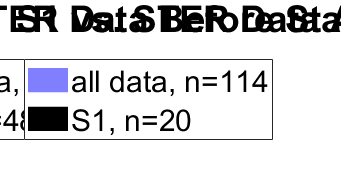

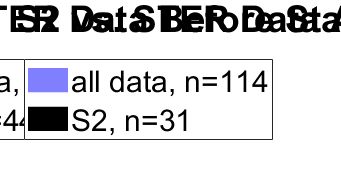

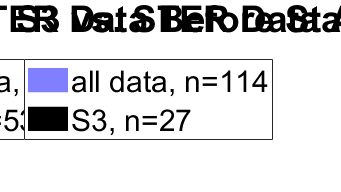

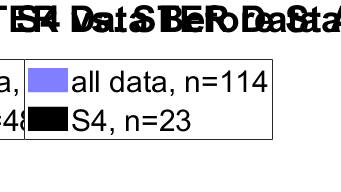

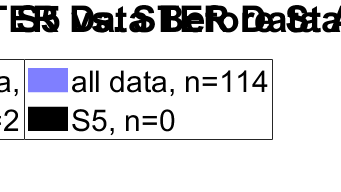

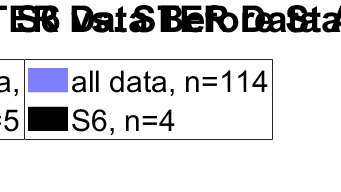

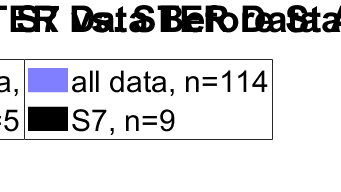

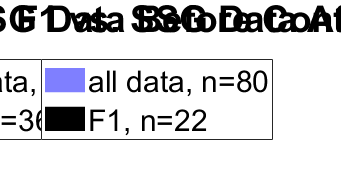

%%%%%%%%%%%%%%%%%%%%%%
%%% Supplemental Figures
%%%%%%%%%%%%%%%%%%%%%%
%% plot each receptor at each site individually by contribution for before/after controls (startup)
allDiffData = {diffSTER, diffSSG, diffCOV(~indsShutdown, :)}; % all near-source sites
allControlsDate = {controlsSTER, controlsSSG, controlsCOV}; % all controls dates
siteNames = {'STER', 'SSG', 'COV'};
medianData = struct(); % instantiate for later storage
receptorNames = struct(); % names of each receptor
receptorNames.STER = {'S1', 'S2', 'S3', 'S4', 'S5', 'S6', 'S7'}; % STER
receptorNames.SSG = {'F1', 'F2', 'F3', 'F4'}; % SSG
receptorNames.COV = {'C1', 'C2', 'C3', 'C4', 'C5', 'C7', 'C8', 'C9'}; % COV
indsReceptor = struct(); % column position of each receptor
indsReceptor.STER = {[1, 2], [3, 4],  [5, 6], [7, 8], 9, 10, 11}; % STER
indsReceptor.SSG = {[1, 2], [3, 4],  5, [6, 7]}; % SSG
indsReceptor.COV = {1, [2, 3], [4, 5], [6, 7], [8, 9], 10, 11, 12}; % SSG
allBinWidths = {0.001, 0.0015, 0.0015}; % grab all bin widths used
allXlims = {[-0.0208, 0.0208], [-0.021, 0.031], [-0.0209, 0.0259]};
allXticks = {-0.020:0.01:0.020, -0.02:0.01:0.03, -0.020:0.01:0.020};
allYlims = {[0, 0.6], [0, 0.8], [0, 0.8]};

%%% export figures
cd ../Figures/'Near Source Receptors' % change to figure folder

for i = 1:length(allDiffData) % iterate through all receptors
    diffData = allDiffData{i}; % choose particular diffdata
    siteName = siteNames{i}; % grab particular site name
    controlsDate = allControlsDate{i}; % grab particular site controls

    medianVal = struct(); % instantiate structure for storing medians

    % separate out data before and after
    indsBefore = diffData.Properties.RowTimes < controlsSSG;
    dataBefore = unravelTT(diffData(indsBefore, :));
    indsAfter = diffData.Properties.RowTimes >= controlsSSG;
    dataAfter = unravelTT(diffData(indsAfter, :));

    % grab median value
    medianVal.before = median(dataBefore);
    medianVal.after = median(dataAfter);

    % iterate to plot data from all receptors
    for j = 1:length(indsReceptor.(siteName))
        receptorName = receptorNames.(siteName){j}; % grab receptor name
        inds = indsReceptor.(siteName){j}; % grab receptor columns

        fig = figure('Position', get(0, 'Screensize')); %for saving the figure
        tiledlayout(1, 2)

        %% do before controls first
        ax = nexttile;
        hold on
        grid on
        box on

        %%all data
        h = histogram(dataBefore, "Normalization", "probability");
        h.BinWidth = allBinWidths{i};
        h.EdgeColor = "none"; %remove outer outline
        h.FaceAlpha = 0.5;
        h.FaceColor = 'b';

        %%this particular receptor's data
        h1 = histogram(unravelTT(diffData(indsBefore, inds)));
        h1.BinWidth = allBinWidths{i};
        h1.EdgeColor = "none"; %remove outer outline
        h1.FaceAlpha = 1;
        h1.FaceColor = 'k';
        h1.BinCounts = h1.BinCounts/length(dataBefore); %normalize to other plot
        medianVal.(strcat(receptorName,'b')) = median(unravelTT(diffData(indsBefore, inds)));

        %%line at SDK uncertainties to signify comparison
        xline(0.00126, "--", "color", [0.3, 0.3, 0.3], "LineWidth", 1.3)
        xline(-0.00126, "--", "color", [0.3, 0.3, 0.3], "LineWidth", 1.3)

        %%lims
        xlim(allXlims{i})
        xticks(allXticks{i})
        ylim(allYlims{i})

        %%labels
        pbaspect([1.3, 1, 1])
        ax.FontSize = 25;
        xlabel("AR Enhancement")
        ylabel("Normalized Observation Counts")
        if i == 1
            endStr = "Startup"; % for STER
        else
            endStr = "Controls"; % for COV and SSG
        end
        title(strcat(receptorName, " vs. ", siteNames{i}, " Data Before ", endStr))

        legend(strcat("all data, n=", num2str(length(dataBefore))), ...
            strcat(receptorName, ", n=", num2str(length(unravelTT(diffData(indsBefore, inds))))), ...
            "location", "northeast")
        hold off

        %% do after controls next
        ax = nexttile;
        hold on
        grid on
        box on

        %%all data
        h = histogram(dataAfter, "Normalization", "probability");
        h.BinWidth = allBinWidths{i};
        h.EdgeColor = "none"; %remove outer outline
        h.FaceAlpha = 0.5;
        h.FaceColor = 'b';

        %%this particular receptor's data
        h1 = histogram(unravelTT(diffData(indsAfter, inds)));
        h1.BinWidth = allBinWidths{i};
        h1.EdgeColor = "none"; %remove outer outline
        h1.FaceAlpha = 1;
        h1.FaceColor = 'k';
        h1.BinCounts = h1.BinCounts/length(dataAfter); %normalize to other plot
        medianVal.(strcat(receptorName,'a')) = median(unravelTT(diffData(indsAfter, inds)));

        %%line at SDK uncertainties to signify comparison
        xline(0.0012, "--", "color", [0.3, 0.3, 0.3], "LineWidth", 1.3)
        xline(-0.0012, "--", "color", [0.3, 0.3, 0.3], "LineWidth", 1.3)

        %%lims
        xlim(allXlims{i})
        xticks(allXticks{i})
        ylim(allYlims{i})

        %%labels
        pbaspect([1.3, 1, 1])
        ax.FontSize = 25;
        xlabel("AR Enhancement")
        ylabel("Normalized Observation Counts")
        if i == 1
            endStr = "Startup"; % for STER
        else
            endStr = "Controls"; % for COV and SSG
        end
        title(strcat(receptorName, " vs. ", siteNames{i}, " Data After ", endStr))

        legend(strcat("all data, n=", num2str(length(dataAfter))), ...
            strcat(receptorName, ", n=", num2str(length(unravelTT(diffData(indsAfter, inds))))), ...
            "location", "northeast")
        hold off

        %% export figure
        a = annotation('rectangle',[0 0 1 1],'Color','w'); %add padding
        fn = strcat(receptorName, ".png");
        exportgraphics(fig, fn)
        delete(a) %make plot interactive again
    end

    medianData.(siteName) = medianVal; % store median data
end


cd ../../Data